## 1. Competition Overview & Baseline Parameters

The objective of the 2027 IMechE UAS Challenge is to design and build a subscale demonstrator of a firefighting UAV (Maximum Take-Off Mass $\le 10$ kg) capable of autonomously navigating and dispensing a water payload at low altitude over a predefined waypoint.   

The competition utilizes three distinct flight missions: Mission 1 (Empty Flight, 200 points), Mission 2 (Payload Delivery, 400 points + 60 Energy Efficiency points), and Mission 3 (Manual Handling, 50 points). The following script establishes the baseline evaluation parameters for a fully autonomous flight profile

% =========================================================================
% 1. Baseline Team Parameters Initialization
% =========================================================================
bestTeam.MTOM = 9.5;             % kg (Must be <= 10.0 kg)
bestTeam.PayloadMass = 2.5;      % kg (Target water payload)
bestTeam.MF = bestTeam.PayloadMass / bestTeam.MTOM; % Mass Fraction
bestTeam.NavWaypoints = 20;      % 2 laps of 10 waypoints for M2 approach
bestTeam.ReturnWaypoints = 10;   % 1 lap of 10 waypoints for M2 return
bestTeam.EnergyConsumed = 150.0; % Wh (Estimated energy for M2 flight)

% Mission 1 Score Formulation (Empty Flight)
% Auto take-off in box (20), 20 waypoints @ 6 pts each (120), Auto landing in box full stop (60)
score.Max.M1 = 20 + 120 + 60; 

% Mission 2 Base Score Formulation (Payload Flight)
% Auto take-off in box (20), Auto landing in box full stop (60), Return navigation 10 waypoints @ 2 pts (20)
score.Max.M2_Base = 20 + 60 + 20;

## 2. Mission 2: Navigation Score and Mass Fraction (MF) Correlation

In Mission 2, the outbound navigation score is mathematically tied to the aircraft's Mass Fraction (MF), calculated as Payload Mass divided by MTOM. 

The score formula is: $\left(1+2*\textrm{MF}\;\right)*\textrm{Number}\;\textrm{of}\;\textrm{waypoints}\;\textrm{flown}*3\;$ . 

The following analysis evaluates how increasing payload mass against a fixed MTOM scales the navigation score.

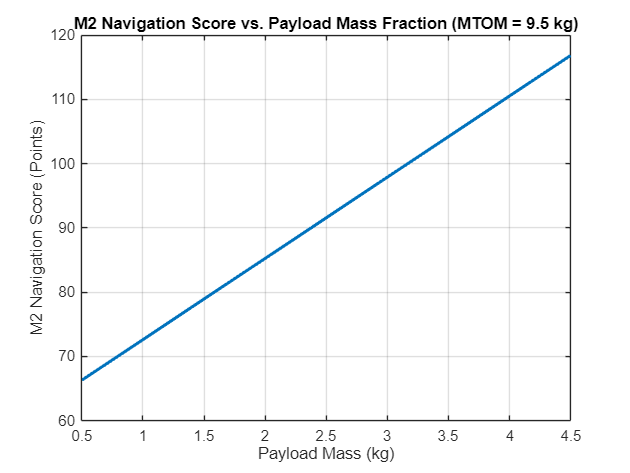

% =========================================================================
% 2. Mass Fraction Sensitivity on Navigation Score
% =========================================================================
% Defining a payload mass vector from 0.5 kg to 4.5 kg
team.Array.PayloadMass = linspace(0.5, 4.5, 50)';
team.MTOM_Fixed = 9.5; % kg

% Calculating Mass Fraction (MF)
team.Array.MF = team.Array.PayloadMass ./ team.MTOM_Fixed;

% M2 Navigation Score: (1 + 2 * MF) * waypoints * 3
M2_Nav_Score = (1 + 2 .* team.Array.MF) .* bestTeam.NavWaypoints .* 3;

figure();
plot(team.Array.PayloadMass, M2_Nav_Score, 'LineWidth', 2, 'Color', '#0072BD');
xlabel('Payload Mass (kg)');
ylabel('M2 Navigation Score (Points)');
title('M2 Navigation Score vs. Payload Mass Fraction (MTOM = 9.5 kg)');
grid on;

**Engineering Inference:** The navigation score scales linearly with payload mass, meaning the aerodynamic and structural teams must collaborate to strip empty weight from the airframe. Every gram saved in airframe weight allows for more payload, increasing the MF and compounding the navigation multiplier. 

## 3. Mission 2: Payload Delivery & Autonomy Trade-Off

Payload delivery awards points based on the level of autonomy and accuracy: Automatic release over target ($\textrm{Water}\;\textrm{Mass}*30$), Automatic release ($\textrm{Water}\;\textrm{Mass}*20$), and Manual release ($\textrm{Water}\;\textrm{Mass}*10$). This section visualizes the total Mission 2 score across these three autonomy states.   

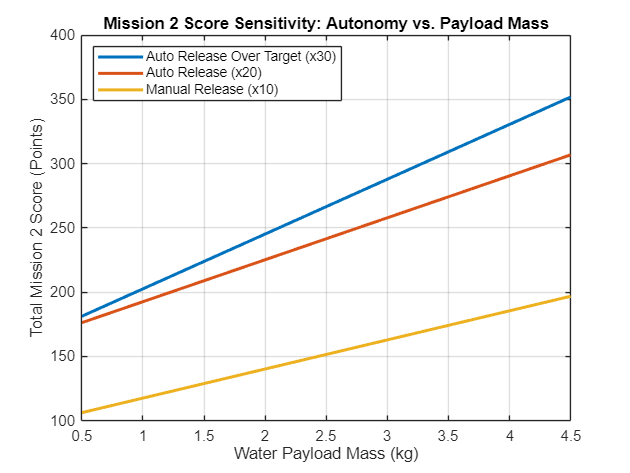

% =========================================================================
% 3. Autonomy and Delivery Accuracy Trade-Off (With Hard Caps)
% =========================================================================
% Defining a payload mass vector from 0.5 kg to 5.0 kg
team.Array.PayloadMass = linspace(0.5, 5.0, 50)';
team.MTOM_Fixed = 9.5; % kg
team.Array.MF = team.Array.PayloadMass ./ team.MTOM_Fixed;

% M2 Navigation Score: (1 + 2 * MF) * waypoints * 3 (Capped at 120 points)
M2_Nav_Score = min((1 + 2 .* team.Array.MF) .* bestTeam.NavWaypoints .* 3, 120);

% Delivery Scores based on Autonomy Levels (Capped at 120 points)
drop_auto_target = min(team.Array.PayloadMass .* 30, 120);
drop_auto_miss   = min(team.Array.PayloadMass .* 20, 120);
drop_manual      = min(team.Array.PayloadMass .* 10, 120);

% Total M2 Scores combining Base, Nav, and Delivery
% (Assuming full 100 points for auto takeoff/landing/return)
M2_Total_AutoTarget = score.Max.M2_Base + M2_Nav_Score + drop_auto_target;
M2_Total_AutoMiss   = score.Max.M2_Base + M2_Nav_Score + drop_auto_miss;

% (Manual penalty: Takeoff drops 20->5, Landing drops 60->10)
M2_Base_Manual = 5 + 10 + 20; 
M2_Total_ManualDrop = M2_Base_Manual + M2_Nav_Score + drop_manual;

figure();
plot(team.Array.PayloadMass, M2_Total_AutoTarget, 'LineWidth', 2, 'DisplayName', 'Auto Release Over Target (x30)');
hold on;
plot(team.Array.PayloadMass, M2_Total_AutoMiss, 'LineWidth', 2, 'DisplayName', 'Auto Release (x20)');
plot(team.Array.PayloadMass, M2_Total_ManualDrop, 'LineWidth', 2, 'DisplayName', 'Manual Release (x10)');
hold off;

legend('Location', 'NorthWest');
xlabel('Water Payload Mass (kg)');
ylabel('Total Mission 2 Score (Points)');
title('Mission 2 Score Sensitivity: Autonomy vs. Payload Mass');
grid on;

**Engineering Inference:** A fully autonomous aircraft accurately dropping 1.5 kg of water will severely outscore an aircraft that must revert to manual control to drop 4.0 kg. The control team's ability to refine GPS waypoint tracking and release latency is mathematically more valuable than simply carrying a larger payload. 

## 4. Energy Efficiency 3D Surface Analysis

Up to 60 bonus points are distributed to the top 10 teams based on an Energy Efficiency metric: $\left(\frac{\textrm{Waypoints}\;\textrm{Navigated}*\textrm{Payload}\;\textrm{Mass}}{\textrm{Energy}\;\textrm{Consumed}\;\left(\textrm{Wh}\right)}\right)$. The 3D surface plot below evaluates how aerodynamic efficiency (Wh consumed) and payload capacity interact to drive this metric.

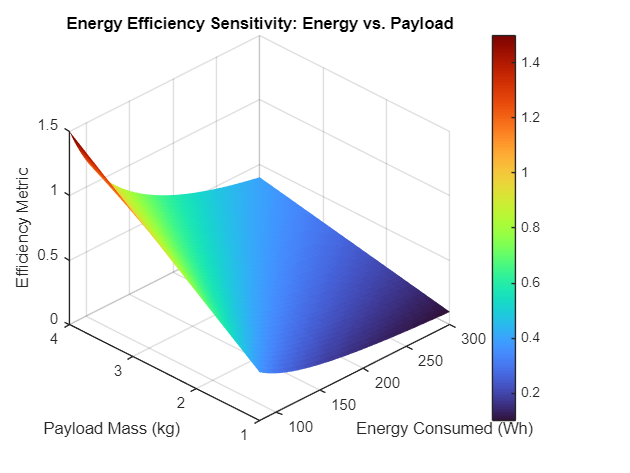

% =========================================================================
% 4. Energy Efficiency 3D Surface Plot
% =========================================================================
% Defining vectors for Energy Consumed and Payload Mass
energy_vector = linspace(80, 300, 50); % Wh
payload_vector = linspace(1.0, 4.0, 50); % kg
total_waypoints = bestTeam.NavWaypoints + bestTeam.ReturnWaypoints; % 30 waypoints total

% Preparing mesh grid for 3D plot
[X_energy, Y_payload] = meshgrid(energy_vector, payload_vector);

% Efficiency Metric Calculation
Efficiency_Metric = (total_waypoints .* Y_payload) ./ X_energy;

figure();
surface(X_energy, Y_payload, Efficiency_Metric, 'EdgeColor', 'none')
colormap('turbo');
colorbar;
view(-45, 35); % Angled for better 3D visibility

xlabel('Energy Consumed (Wh)');
ylabel('Payload Mass (kg)');
zlabel('Efficiency Metric');
title('Energy Efficiency Sensitivity: Energy vs. Payload');
grid on;

**Engineering Inference:** The surface plot reveals a steep gradient where low energy consumption massively spikes the efficiency metric. If increasing the payload mass from 2.0 kg to 3.0 kg requires a larger, draggier airframe that doubles the energy consumption (e.g., from 100 Wh to 200 Wh), the resulting efficiency metric plummets. Powertrain and Aerodynamics must find the cruise velocity that maximizes the lift-to-drag ratio while satisfying the 15-minute flight endurance requirement. 